## PHASE 0: Host Signal Generation and Initialization

This phase generates the host audio signal that will later be used for watermark

embedding. Instead of using a recorded audio file, a synthetic multi-tone signal

is created to simulate an audio-like signal with multiple frequency components.

clc;
clear;
close all;
fs=8000; %Sampling Frequency=8000 samples per second
T=1;
t=0:1/fs:T-1/fs;

- Duration of the signal = **1 second**

- Total samples = $f_s \times  T = 8000$

This creates a time vector with:

- a starting time of 0 seconds

- a step size of $\frac{1}{f_s}$ seconds

- a total of $N = f_s \times T = 8000$ samples

Each element of $t$ corresponds to one audio sample

%Multitone signal - audio like
f1=300; % Low frequency component
f2=600; % Mid frequency component
f3=1200; % High frequency component
%Audio signal
x=sin(2*pi*f1*t)+0.8*sin(2*pi*f2*t)+0.5*sin(2*pi*f3*t);
sound(x, fs)

Different amplitudes are used to simulate realistic audio energy distribution across frequencies.

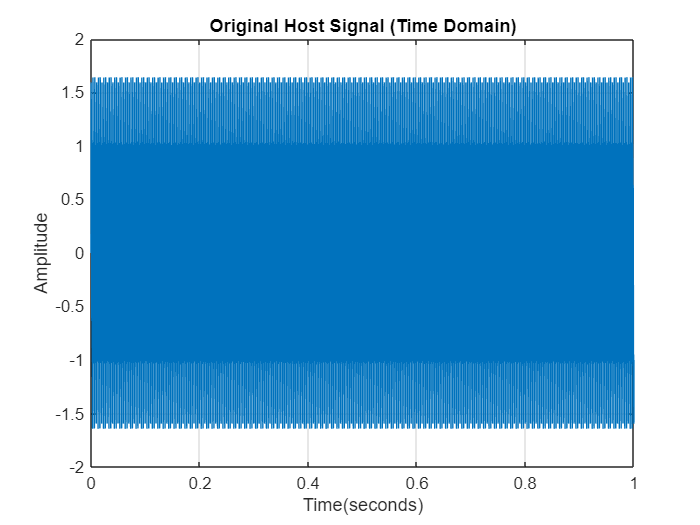

%Time Domain Plots
figure
plot(t,x);
xlabel('Time(seconds)');
ylabel('Amplitude');
title("Original Host Signal (Time Domain)");
grid on;

sound(x, fs)

The generated signal is plotted in the time domain to observe its waveform before watermark embedding.

This plot serves as the baseline reference for evaluating distortion introduced by watermarking in later phases.

The host signal is transformed from the time domain to the frequency domain using the Fast Fourier Transform (FFT).

This transformation allows us to analyze the frequency components present in the signal and forms the basis for frequency-domain watermark embedding in later phases.

No watermark is embedded in this phase. The goal is only to observe and understand the spectral content of the original host signal.

N=length(x); % Signal Length

This value determines:

- the resolution of the FFT,

- the spacing between frequency bins,

- the frequency axis used for spectral analysis.

X=fft(x);

The FFT converts the discrete-time signal into complex frequency components.

Each FFT coefficient represents the contribution of a specific frequency to the overall signal.

f=(0:N-1)*(fs/N);

The frequency axis corresponding to the FFT is defined as $f = (0 : N-1)\frac{f_s}{N}$

Here, each FFT index is mapped to its corresponding frequency value in Hertz.

Only the first half of the FFT spectrum is plotted because the FFT of a real-valued signal is symmetric.

The magnitude spectrum is normalized by dividing by $N$ to ensure proper amplitude scaling.

This plot reveals the dominant frequency components present in the host signal and serves as a reference for selecting suitable frequency bins for watermark embedding in later phases.

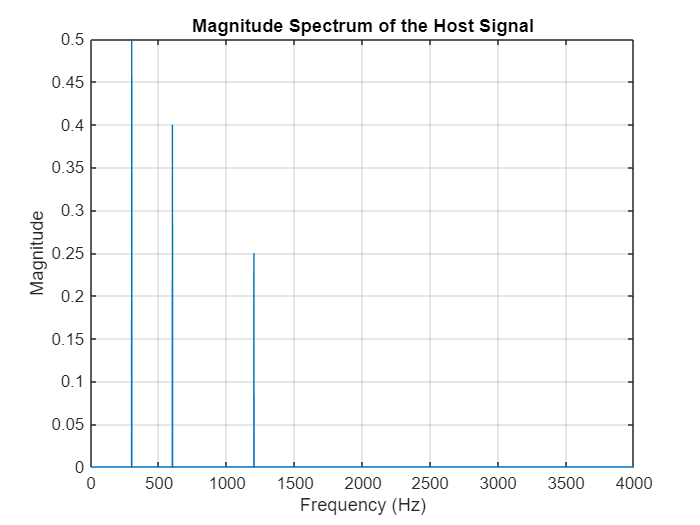

figure;
plot(f(1:N/2), abs(X(1:N/2))/N);
xlabel("Frequency (Hz)");
ylabel("Magnitude");
title("Magnitude Spectrum of the Host Signal");
grid on;

## **PHASE 1 - Watermark Sequence Generation**

In this phase, the digital watermark sequence is generated. The watermark represents the information that will be embedded into the host signal in later phases. A random binary sequence is used to simulate a generic watermark.

This binary watermark is then converted into a bipolar form to make it suitable for correlation-based detection and optimization.

rng(24250)

The random number generator is initialized using a fixed seed to ensure reproducibility$rng(24250)$

Using a fixed seed ensures that the same watermark sequence can be regenerated when required, which is useful for debugging and controlled experimentation.

L_max = 100; %Upper limit on watermark length
L_w = L_max; %Watermark length fixed
W = randi([0 1],1,L_w) %Random no 0 or 1 for watermark

W =      0     1     1     0     1     0     1     0     0     0     1     1     1     1     1     0     1     0     1     1     1     1     1     1     1     0     0     0     1     1     0     1     1     1     1     0     0     0     1     0     1     0     0     0     1     0     1     0     0     1


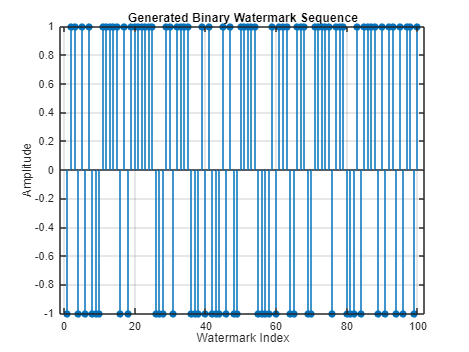

%Conversion into Bipolar form
% 0 -> -1 and 1 -> +1
W_bipolar = 2*W - 1; %This makes it zero mean
figure;
stem(W_bipolar, 'filled');
xlabel('Watermark Index');
ylabel('Amplitude');
title('Generated Binary Watermark Sequence');
grid on;

## PHASE 2 - Key-Based Mid-Band Frequency Bin 

In this phase, the frequency locations used for watermark embedding are selected.

Watermarking is not performed on all frequency components; instead, embedding is restricted to a carefully chosen mid-frequency band to balance imperceptibility and robustness.

A secret key is used to randomly select embedding locations from this safe frequency band. This ensures security and reproducibility of the watermarking process.

N=length(x);
f=(0:N-1)*(fs/N);

Very low-frequency components are perceptually important, while very high-frequency components are vulnerable to filtering.

Therefore, a mid-frequency band is selected for watermark embedding.

The lower and upper frequency limits are defined as

$f_{low}= 400  Hz$ and $f_{high}= 2000  Hz$

Only frequency bins within this range are considered as candidates for embedding.

f_low = 400;
f_high = 2000;
%Here we are taking a safe embedding band (Mid band)

Since the FFT of a real-valued signal is symmetric, only the first half of the spectrum is used:


$$halfN = \lceil \frac{N}{2} \rceil$$


This avoids redundant frequency components and simplifies processing.

halfN=floor(N/2);

The set of candidate embedding bins is obtained by selecting frequency indices that lie within the chosen mid-frequency band:


$$\text{cand} = \{m \mid f(m) \in [f_{\text{low}}, f_{\text{high}}]\}$$


This candidate set defines all allowable frequency locations for watermark embedding.

cand=find(f(1:halfN)>=f_low & f(1:halfN)<= f_high);

A secret key is used to initialize the random number generator: $rng(24250)$

From the candidate set, a number of frequency bins equal to the watermark length is randomly selected.

This ensures that each watermark symbol is embedded into a unique frequency bin. The selected bin indices are sorted for consistent processing and visualization.

key=24250;
rng(key);
M_max=1000; % Sets an upper bound on candidate bin pool size
M=length(W_bipolar); % Determines number of bins to select, equal to watermark length.

Randomly selects $M$ unique embedding bins from candidate set.

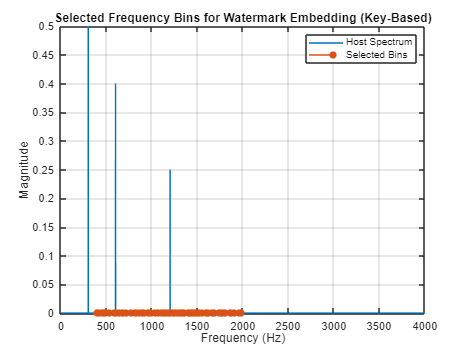

idx=cand(randperm(length(cand),M));
idx=sort(idx); % Sorts selected bins for clean indexing and plotting.
figure;
plot(f(1:halfN), abs(X(1:halfN))/N); hold on;
stem(f(idx), 0.001*ones(size(idx)), 'filled'); % markers at selected bins
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Selected Frequency Bins for Watermark Embedding (Key-Based)');
grid on;
legend('Host Spectrum','Selected Bins');

##  PHASE 3 - Watermark Embedding in the Frequency Domain

In this phase, the watermark is embedded into the host signal in the frequency domain.

The embedding is performed by slightly modifying the FFT coefficients at selected frequency bins. Only the magnitude of the FFT coefficients is altered, while the phase information is preserved.

A small embedding strength is used to ensure that the watermark remains imperceptible. To maintain a real-valued time-domain signal after inverse FFT, conjugate symmetry of the FFT spectrum is preserved.

The embedding strength is defined as $\alpha=0.05$

This value controls the trade-off between imperceptibility and detectability:

- smaller $\alpha$ → less distortion but weaker detection

- larger $\alpha$ → stronger detection but more audible distortion

alpha=0.05; %Small value

The watermarked spectrum is initialized as a copy of the original FFT spectrum:


$$X_w=X$$


This ensures that only selected frequency bins are modified during embedding.

Xw=X; %Watermarked Spectrum initialisation

For each selected frequency bin:

- the corresponding watermark symbol is added to the FFT coefficient,

- the conjugate symmetric bin is updated to preserve signal reality.

%Embed Watermark
for i = 1:length(idx)
    k=idx(i); % Retrieves the FFT bin index corresponding to the current watermark symbol.
    Xw(k) = X(k) + alpha*W_bipolar(i); % Embeds the watermark by modifying the FFT coefficient.
    %Conjugate Symmetric Bin
    k_sym = N - k + 2;
    Xw(k_sym)= conj(Xw(k)); % This guarantees that the inverse FFT produces a real-valued time-domain signal.
end
%Inverse FFT to get the watermarked Signal

## PHASE 4 - ADMM-Based Optimization of Watermark Embedding

In this phase, the initially embedded watermark is refined using the Alternating Direction Method of Multipliers (ADMM).

The purpose of this refinement is to control the trade-off between distortion and watermark detectability in a systematic manner.

Instead of directly embedding the watermark using a fixed strength, ADMM is used to adjust the embedding perturbation such that:

- the overall distortion is minimized

- the correlation between the watermark and the embedding perturbation satisfies predefined detectability constraints.

This phase operates only on the selected frequency bins and does not alter the remaining spectrum.

The ADMM penalty parameter is defined as $\rho=1$

This parameter controls the relative weight of the constraint enforcement during optimization.

The detectability bounds are defined as $    \tau \le w^T d \le \tau_{\text{max}}$�

where:

- $\tau = 1$ is the lower bound ensuring watermark detectability,

- $\tau_{\max} = 2$ is the upper bound preventing excessive distortion.

The maximum number of ADMM iterations is set to 30, which is sufficient for convergence in practice.

rho     = 1;        % ADMM penalty parameter
tau     = 1;     % lower detectability bound (tune if needed)
tau_max = 2.00;     % upper detectability bound (tune if needed)
maxIter = 30;       % ADMM iterations (20–50 is enough)

The initial embedding perturbation is computed from the difference between the initially embedded spectrum and the original spectrum:


$$d_0 = \mathrm{Re}\{X_w(\mathrm{idx}) - X(\mathrm{idx})\}$$


This vector represents the initial frequency-domain modifications applied during Phase 3.

The watermark vector is represented as a column vector : $w \in \{-1, +1\}^{M\times1}$

where $M$ is the watermark length.

% Xw currently contains the "initial embedded spectrum" from Phase 3
d0 = real(Xw(idx) - X(idx));   % initial perturbation at selected bins (Mx1)
w  = W_bipolar(:);             % watermark vector (Mx1), bipolar {-1,+1}

% Ensure column vectors
d0 = d0(:);

The ADMM variables are initialized as follows:

- $d$ is the optimization variable representing the embedding perturbation,

- $z$ is a constrained copy of $d$

- $u$ is the scaled dual variable.

The squared norm of the watermark vector, $\|w\|_2$

is precomputed to simplify the projection step.

d = d0;                         % variable to optimize
z = d0;                         % constrained copy
u = zeros(size(d0));            % scaled dual variable
w_norm2 = norm(w)^2;            % ||w||^2 for projection

The ADMM algorithm iteratively updates the variables $d$, $z$, and $u$.

**(a) d-update (distortion minimization)**

The update minimizes the quadratic distortion term while keeping $d$ close to the constrained variable $z$:


$$d^{(t+1)} = \frac{\rho}{1+\rho}(z^{(t)}-u^{(t)})$$


**(b) z-update (projection onto detectability constraints)**

The vector $y = d + u$ is projected onto the constraint slab defined by�


$$    \tau \le w^T d \le \tau_{\text{max}}$$


If the constraint is already satisfied, no modification is applied.

**(c) Dual variable update**

The dual variable is updated as


$$u^{(t+1)} = u^{(t)} + (d^{(t+1)} - z^{(t+1)})$$


These steps are repeated for a fixed number of iterations until convergence.

for it = 1:maxIter
    % (a) d-update: distortion minimization (quadratic, closed-form)
    % d^{t+1} = argmin 0.5||d||^2 + (rho/2)||d - z + u||^2
    d = (rho/(1+rho)) * (z - u);

    % (b) z-update: projection onto slab  tau <= w^T z <= tau_max
    y = d + u;
    wy = w.' * y;

    if wy < tau
        z = y + ((tau - wy)/w_norm2) * w;
    elseif wy > tau_max
        z = y - ((wy - tau_max)/w_norm2) * w;
    else
        z = y;  % already feasible
    end

    % (c) dual update
    u = u + (d - z);
end

After ADMM convergence, the optimized perturbation vector $d$ is applied back to the FFT spectrum at the selected frequency bins:

$X_w(k)=X(k)+d_i$�

Conjugate symmetry is enforced to ensure that the inverse FFT produces a real-valued time-domain signal.

% Replace the originally embedded values at idx using optimized d
for i = 1:length(idx)
    k = idx(i);
    Xw(k) = X(k) + d(i);

    % Maintain conjugate symmetry for a real time-domain signal
    k_sym = N - k + 2;
    Xw(k_sym) = conj(Xw(k));
end

Finally, the correlation value: $w^T d$

is computed and displayed to verify that the detectability constraint has been satisfied.

final_corr = w.' * d;
disp(['ADMM final w^T d = ', num2str(final_corr)]);

ADMM final w^T d = 1


disp(['Check: length(idx)=', num2str(length(idx)), ' , length(W_bipolar)=', num2str(length(W_bipolar))]);

Check: length(idx)=100 , length(W_bipolar)=100


## Phase 5 - Inverse FFT and Time Domain Reconstruction

In this phase, the optimized watermarked frequency spectrum $X_w$ is transformed back into the time domain using the inverse FFT (IFFT). This produces the final watermarked audio signal.

Because conjugate symmetry was maintained during embedding and ADMM refinement, the IFFT result should be real-valued. A small imaginary part may still appear due to numerical precision, so the real part is taken explicitly.

Finally, the original host signal and the reconstructed watermarked signal are plotted to visually compare waveform similarity and verify that watermark embedding does not introduce obvious distortion.

The time-domain watermarked signal is obtained as 


$$x_w = \mathrm{Re}\{ifft(X_w)\}$$


This converts the modified frequency components back into a discrete-time waveform.

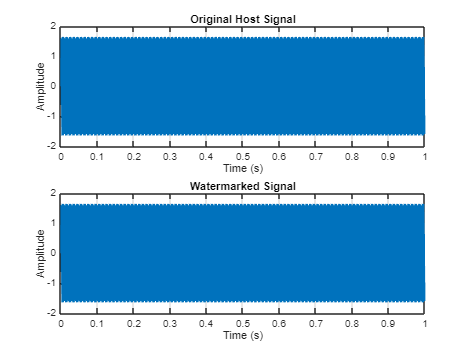

x_w=real(ifft(Xw));
figure;
subplot(2,1,1);
plot(t, x);
title('Original Host Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
subplot(2,1,2);
plot(t, x_w);
title('Watermarked Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

difference=max(abs(x - x_w))

difference = 6.4136e-05

## PHASE 6 - Blind Watermark Detection

In this phase, the presence of a watermark is detected from the received signal without using the original audio during detection.

This is a blind detection approach.

The detection is performed by:

- taking the FFT of the received signal,

- extracting the FFT coefficients at the same embedding bin indices, and

- computing a correlation score with the watermark sequence.

If the score is larger than a threshold, the watermark is declared present.

In this experiment, the received signal is assumed to be the clean watermarked signal: 

$x_r=x_w$�

In later experiments, $x_r$ may represent an attacked signal (AWGN, filtering, scaling, etc.).

**FFT of the Received Signal**

The received signal is transformed into frequency domain:


$$X_r = \mathrm{fft(x_r)}$$


x_r = x_w;
Xr = fft(x_r);

The detector regenerates the watermark using the same random seed. This is necessary because the detection correlates with the known watermark pattern.

The regenerated watermark length is chosen as


$$L_w=length(idx)$$


The bipolar detection watermark is generated as


$$W_{det}=2W-1$$


This produces a sequence of $-1$ and $+1$ values.

%Regenerate the watermark using the same key
L_w = length(idx);
rng(24250);
W_det = randi([0 1],1,L_w);
W_det = 2*W_det - 1;

The detection score is computed using a correlation-like sum:


$$D = \frac{1}{L_w}\sum_{i=1}^{L_w}\mathrm{Re}\{X_r(k_i)\}W_{\mathrm{det}}(i)$$


where $k_i$ are the selected frequency-bin indices stored in $\text{idx}$.

If a watermark is present, the correlation value $D$ is expected to be noticeably different from the non-watermarked case.

%Detection Stats (Correlation)
D=0;
for i = 1:L_w
    k=idx(i);
    D=D+real(Xr(k))*W_det(i);
end
D=D/L_w;
disp(['Detection Score D = ', num2str(D)]);

Detection Score D = 0.01


A threshold $T$ is used to decide watermark presence:

- If $|D| > T$ → watermark detected

- Otherwise → watermark not detected

Two thresholds are used in this code:

- a simple threshold $T=0$ (quick check),

- a data-driven threshold based on the original audio baseline:


$$T=10|D0|$$


T=0; %If water mark present in our setup it will be >0.
if abs(D)>T
    disp("Watermark Detected");
else
    disp("Watermark not detected");
end

Watermark Detected


To avoid false positives, the detection score is also computed for the original (no watermark) signal: 


$$D = \frac{1}{L_w}\sum_{i=1}^{L_w}\mathrm{Re}\{X_r(k_i)\}W_{\mathrm{det}}(i)$$


where $X_0 = \text{FFT}(x)$.

This baseline score should ideally be close to zero because no watermark is embedded in the original signal. The threshold based on $D_0$ adapts to the signal’s natural correlation with the watermark pattern.

X0 = fft(x);
D0 = 0;
for i = 1:L_w
    k = idx(i);
    D0 = D0 + real(X0(k)) * W_det(i);
end
D0 = D0 / L_w;

T = 10*abs(D0);        % or 5*abs(D0)

disp(['D  = ', num2str(D)]);

D  = 0.01


disp(['D0 = ', num2str(D0)]);

D0 = -8.9855e-13


disp(['T  = ', num2str(T)]);

T  = 8.9855e-12



if abs(D0)>T
    disp("Watermark Detected");
else
    disp("Watermark not detected");
end

Watermark not detected


## Phase 7.1 - Evaluation: SNR + Attacks + Unified detection scores

Imperceptibility is evaluated by treating the embedding distortion as an error signal: $n_{embed}=x-x_w$�

The SNR in dB is computed as


$$SNR_{dB} = 10 \log_{10} \left( \frac{\sum x^2}{\sum n_{embed}^2} \right)$$


A higher SNR indicates that the watermark introduces very little distortion and is therefore more imperceptible.

noise_embed = x - x_w;
SNR_dB = 10*log10( sum(x.^2) / sum(noise_embed.^2) );
disp(['SNR between original and watermarked = ', num2str(SNR_dB), ' dB']);

SNR between original and watermarked = 94.8058 dB


## PHASE 7.2 - Robustness Tests (Attacks)

To test robustness, the watermarked signal is modified using three common operations:

**Attack A (Noise Addition):**

Random Gaussian noise is added:


$$x_{\text{awgn}} = x_w + \sigma \cdot \mathcal{N}(0,1)$$


where $\sigma$ controls the noise strength.

**Attack B (Low-Pass Filtering):**

A Butterworth low-pass filter is applied with cutoff frequency $F_c$.

**Attack C (Amplitude Scaling):**

The signal amplitude is scaled by a constant factor:

$x_{scale}=\beta.x_w$�

%% Attack A: Add noise
sigma = 0.02; % noise strength
x_awgn = x_w + sigma*randn(size(x_w));
%% Attack B: Low-pass filter
Fc = 1500; % cutoff frequency (Hz)
[b,a] = butter(4, Fc/(fs/2), 'low');
x_lpf = filtfilt(b,a, x_w);
%% Attack C: Amplitude scaling
beta = 0.8;
x_scale = beta * x_w;

## PHASE 7.3 - Reusable Detection Function

A detection function is defined to compute the correlation score:


$$D = \frac{1}{L_w}\sum_{i=1}^{L_w}\mathrm{Re}\{X_r(k_i)\}W_{\mathrm{det}}(i)$$


This ensures the same detection computation is applied for:

- clean watermarked signal,

- attacked signals,

- and original signal (no watermark case).

function D = detect_score(x_r, fs, idx, key)
    N = length(x_r);
    Xr = fft(x_r);
    L_w = length(idx);
    rng(key);
    W = randi([0 1], 1, L_w);
    W = 2*W - 1; % bipolar watermark

--- Detection Scores ---


    D = 0;

Original (no watermark): -8.9855e-13


    for i = 1:L_w

Clean watermarked : 0.01


        k = idx(i);

AWGN attacked : -0.18437


        D = D + real(Xr(k)) * W(i);

Low-pass filtered : -0.010239


    end

Amplitude scaled : 0.008


    D = D / L_w;
end

## PHASE 7.4 - Running Detection on All Cases

Detection scores are computed for:

- $x_w$ (clean watermarked),

- $x_{\text{awgn}}$ (noisy),

- $x_{\text{lpf}}$ (low-pass filtered),

- $x_{\text{scale}}$ (amplitude scaled),

- $x $original).

These values are later reported in the Results section to interpret robustness behavior

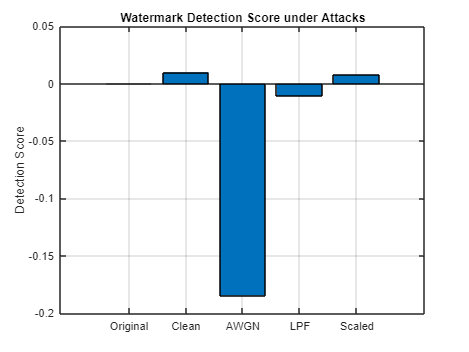

key = 24250; % same key used earlier
D_clean = detect_score(x_w, fs, idx, key);
D_awgn = detect_score(x_awgn, fs, idx, key);
D_lpf = detect_score(x_lpf, fs, idx, key);
D_scale = detect_score(x_scale, fs, idx, key);
D_orig = detect_score(x, fs, idx, key); % should be low / different
disp('--- Detection Scores ---');

disp(['Original (no watermark): ', num2str(D_orig)]);
disp(['Clean watermarked : ', num2str(D_clean)]);
disp(['AWGN attacked : ', num2str(D_awgn)]);
disp(['Low-pass filtered : ', num2str(D_lpf)]);
disp(['Amplitude scaled : ', num2str(D_scale)]);
% Bar plot
scores = [D_orig D_clean D_awgn D_lpf D_scale];
labels = {'Original','Clean','AWGN','LPF','Scaled'};
figure;
bar(scores);
set(gca,'XTickLabel',labels);
ylabel('Detection Score');
title('Watermark Detection Score under Attacks');
grid on;

% clearvars
% % 1. Define Parameters
% Fs = 44100;                    % Sample rate (Hz) - CD quality
% duration = 2;                  % Duration in seconds
% t = 0:1/Fs:duration;           % Time vector
% 
% % 2. Generate the Wave (e.g., 440 Hz Sine wave - Note A)
% freq = 440; 
% y = sin(2*pi*freq*t);
% 
% % 3. Play the Sound
% sound(y, Fs);
